# Questions:

**Q. Plot the following in axis range -> [-6 6 -3 3]:**


$$x=\mathrm{acos}\left(t\right)-\frac{{\mathrm{asin}}^2 t}{\sqrt[\;]{2}}$$



$$y=\mathrm{acos}\left(t\right)\mathrm{sin}\left(t\right)$$


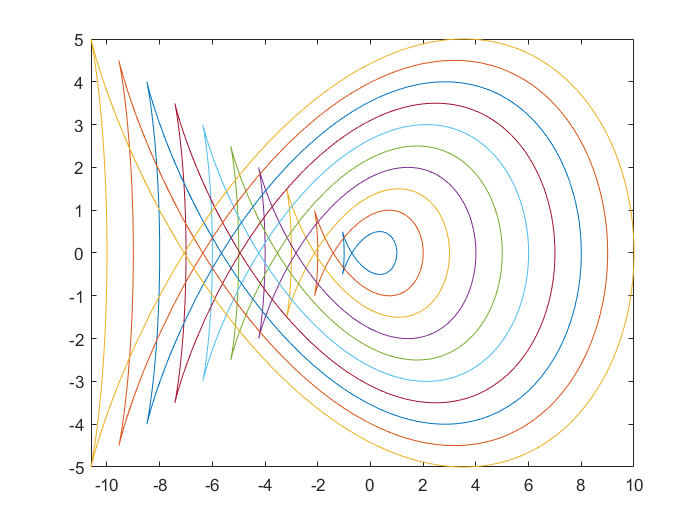

syms t 
axis([-6 5 -5 5]);
for a = 1:10
    x(t) = a*cos(t)-(a*(sin(t))^2)/sqrt(2);
    f(t) = a*cos(t)*sin(t);
    fplot(x(t),f(t))
    hold on
end
hold off

**2.1**

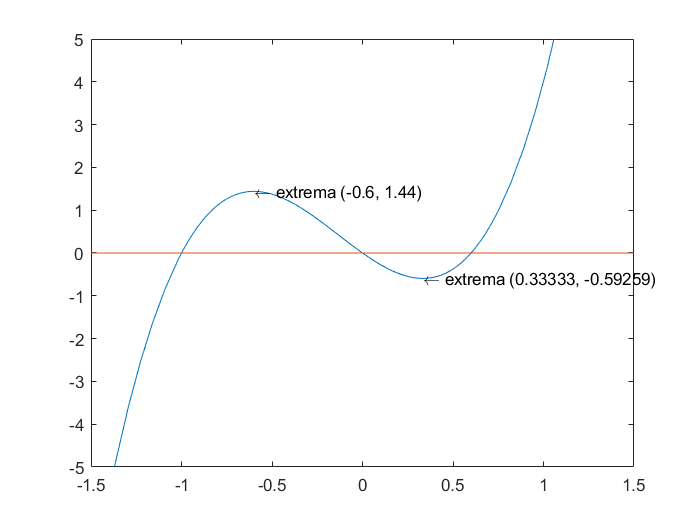

syms f(x)
f(x) = 5*x^3 + 2*x^2 - 3*x;
y1 = diff(f);
xcoordinate = vpasolve(y1==0);
ycoordinate = f(xcoordinate);
fplot(f(x));
hold on
x=0;
fplot(x);
hold off
axis([-1.5 1.5 -5 5]);


text(xcoordinate(1),ycoordinate(1),['\leftarrow extrema (' num2str(double(xcoordinate(1))) ', ' num2str(double(ycoordinate(1))) ')'])
text(xcoordinate(2),ycoordinate(2),['\leftarrow extrema (' num2str(double(xcoordinate(2))) ', ' num2str(double(ycoordinate(2))) ')'])

**2.2**

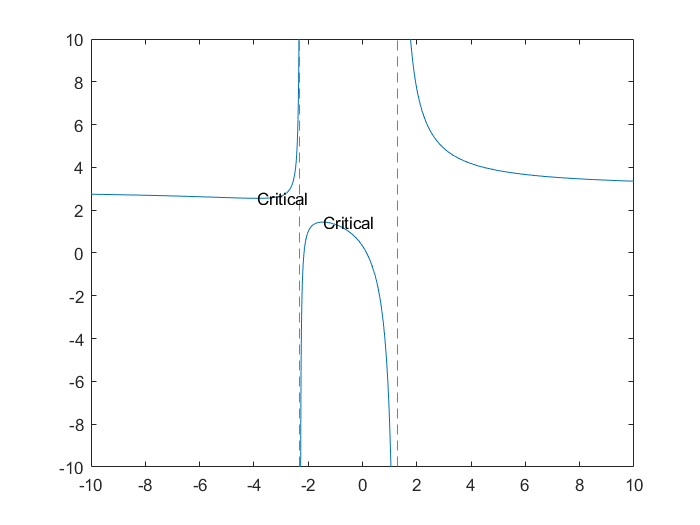

syms f(x)
num = (3*x^2 + 6*x -1);
den = (x^2 + x -3);
f(x) = num / den;

%Finding asymptotes
horizontal = limit(f(x), inf);
horizontal = vpasolve(den==0);

% Finding maxima and minima
y1 = diff(f(x));
x1 = vpasolve(y1 == 0);

%Plotting the function
fplot(f(x))
axis([-10 10 -10 10]);
text(x1,f(x1),'Critical');

syms f(x)
num = 5*x^2 + 8*x -3;
den = 3*x^2 +2;
f(x) = num/den;

%Roots of the function
roots = vpasolve(f(x)==0);

%Asymptotes of the function
horizontal = limit(f(x), inf)

$$horizontal = \frac{5}{3}$$

vertical = vpasolve(den==0)

$$vertical = \left(\begin{array}{c} -0.81649658092772603273242802490196\,\mathrm{i}\\ 0.81649658092772603273242802490196\,\mathrm{i} \end{array}\right)$$

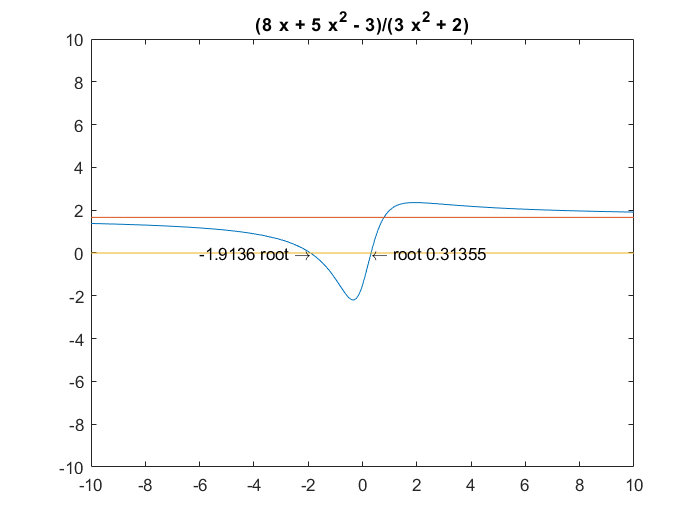


%Extremas
f1(x) = diff(f(x),x);
criticalx = vpasolve(f1(x)==0);
criticaly = f(criticalx);

%Plot them all
fplot(f(x))
axis([-10 10 -10 10])
hold on
plot([-10, 10], [double(horizontal), double(horizontal)])
plot([-10, 10], [0 0])
hold off
text(roots(1),0,[num2str(double(roots(1))),' root \rightarrow'],'HorizontalAlignment','right')
text(roots(2),0,['\leftarrow root ' num2str(double(roots(2)))],'HorizontalAlignment','left')
title(texlabel(f(x)))